**Load Neural Net**

Need to install AlexNet stuff first.

cnn = alexnet;

To use 'alexnet', the following product must be licensed, installed, and enabled:
  Neural Network Toolbox

categories = cnn.Layers(end).ClassNames;

**Read in image**

im1 = imread('~/Documents/Notebooks/p3.matlab.fall2018/data/images/examples/ex1.jpg')
imshow(im1)

**Classify Image**

[prediction, prediction_scores] = classify(cnn, im1);


**Display Scores**

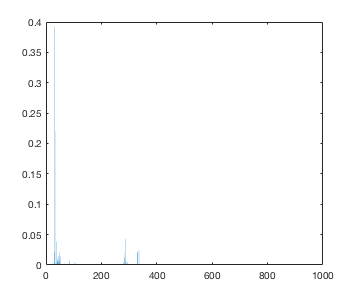

bar(prediction_scores)

**Process Results**

A lot of really small numbers.  Why?  

Let's only look at significant results.  Here, we'll define significant as having a prediction score greater than 0.01.  We first define our significance threshhold...

sig_threshold = 0.01

sig_threshold = 0.0100

sig_scores = prediction_scores > sig_threshold;

sig_scores = 1×1000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   1   0   1   0   0   0   1   0   0   0   0   1


...then make a new bar plot only for those prediction scores higher than our threshold:

bar(prediction_scores(sig_scores))

We're going to change the x tickmarks to be more informative:

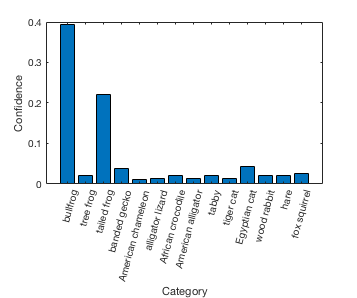

xticklabels(categories(sig_scores))
xtickangle(75)
xlabel("Category")
ylabel("Confidence")

**Discussion**

How did we decide what a "significant" prediction is?  We just chose a random number and decided that it was a significant cutoff.  But how can we defend it?

Let's now make a more statistically defensible cutoff.

sig_threshold = median(prediction_scores) + std(prediction_scores)

sig_threshold = single
0.0145

sig_scores = prediction_scores > sig_threshold

sig_scores = 1×1000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1


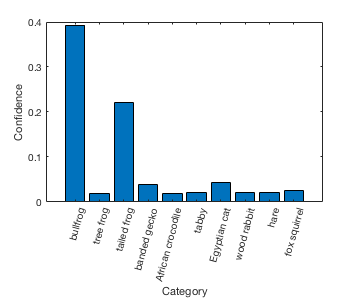

bar(prediction_scores(sig_scores))
xticklabels(categories(sig_scores))
xtickangle(75)
xlabel("Category")
ylabel("Confidence")

**Exercise**

**Turn this into a function**

**Automate it over a  bunch of files**